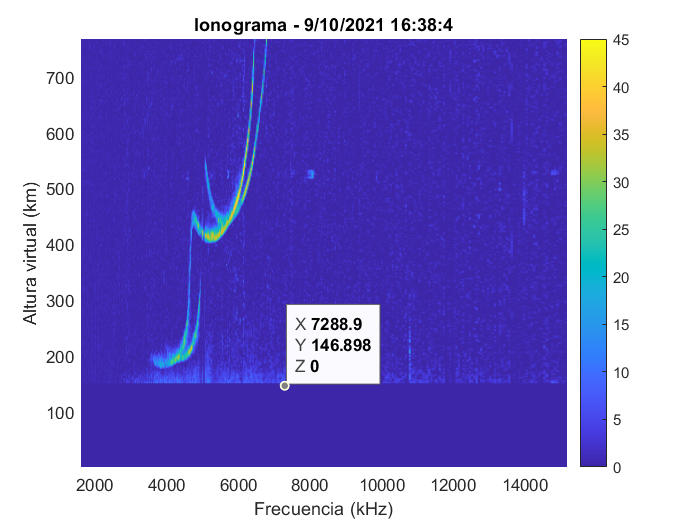

% Get data
IonogramData = GettingRelevantData(zippedDataFrame, FolderNGI, FolderCodesFunc);

% Plot first image
% CustomPlot(IonogramData, IonogramData.totalpowerData)

% Denoising 1
imgDen_1 = Denoising_1(IonogramData.totalpowerData, IonogramData.NoisetotalpowerData, IonogramData.RangeData);
CustomPlot(IonogramData, imgDen_1)

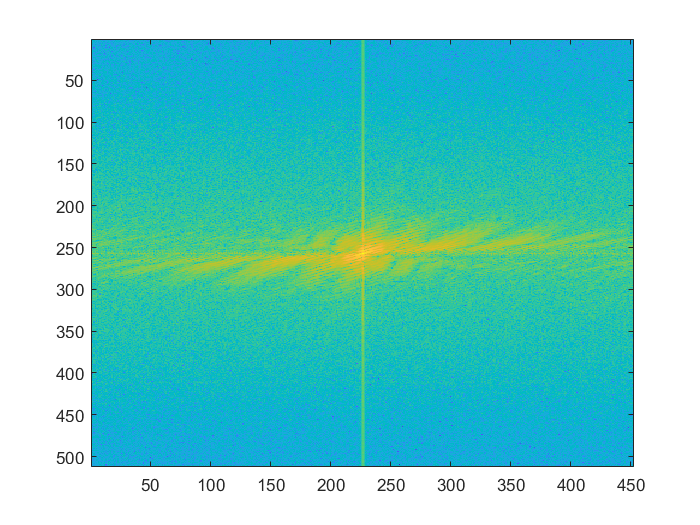

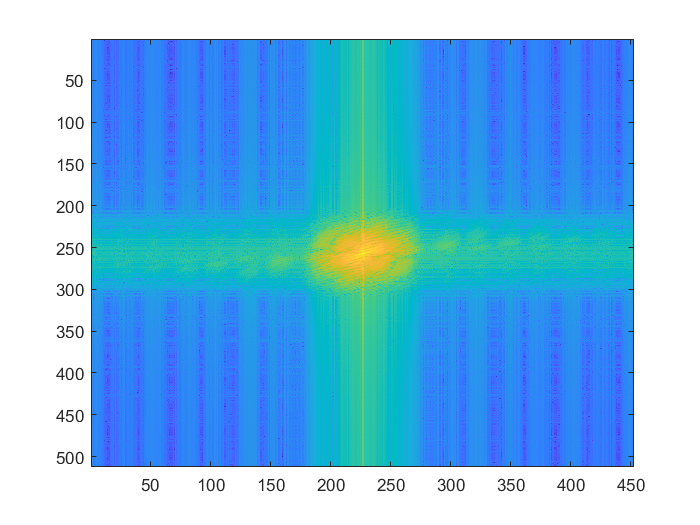


% Freq gauss filter
FreqFilImg = Freqfilt(imgDen_1);

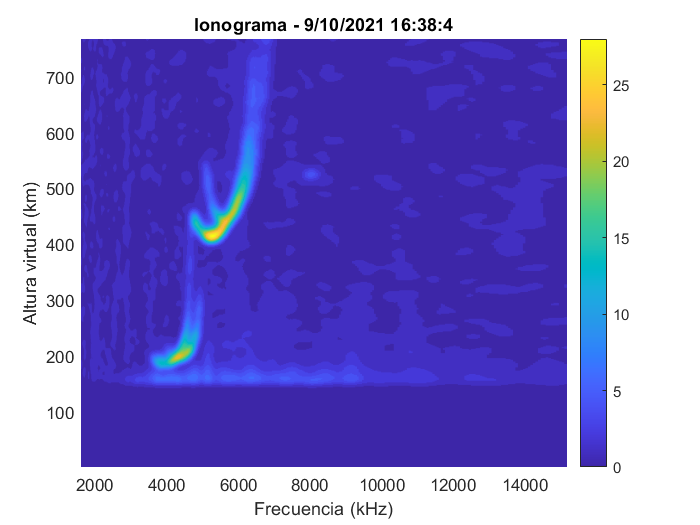

CustomPlot(IonogramData, FreqFilImg)

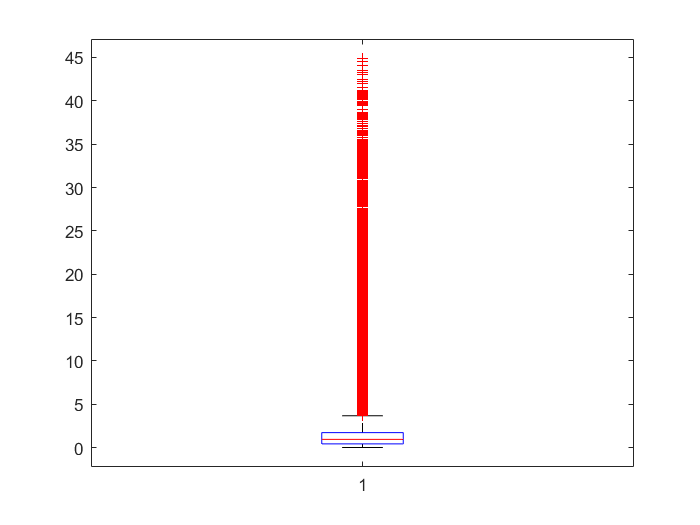


imgVar_ = imgDen_1;
imgVar_ = imgVar_(imgVar_~=0);

boxplot(imgVar_)

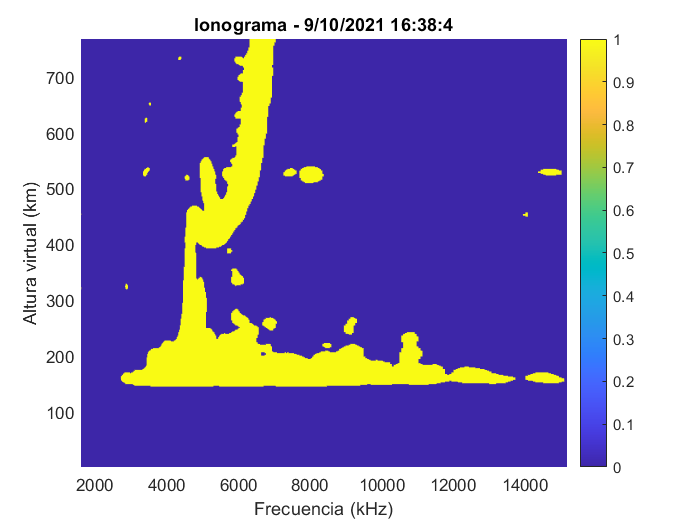

    
% Thresholding global
imgThresh = uint8(ThreshImg_Global(FreqFilImg));
CustomPlot(IonogramData, imgThresh);


imgVar_ = imgDen_1;
imgVar_ = imgVar_(imgVar_~=0);

B = imgaussfilt(imgDen_1, std(double(imgVar_)), 'FilterSize', 3, 'FilterDomain', 'spatial');
B = imgaussfilt(img, std(imgVar_),'FilterDomain',"frequency");

% overlapRatio = ImgIoUGT(zippedDataFrame, FolderCodesFunc, FolderGT, imgThresh)

 I_filtered = I - imfilter( I, fspecial('Gaussian', 5, 1 ) ); 
 imtool( I_filtered );

 
 

% a = im2double(imgDen_1); %// Read in your image
% lap = [-1 -1 -1; -1 8 -1; -1 -1 -1]; %// Change - Centre is now positive
% resp = imfilter(a, lap, 'conv'); %// Change
% 
% %// Change - Normalize the response image
% minR = min(resp(:));
% maxR = max(resp(:));
% resp = (resp - minR) / (maxR - minR);
% 
% %// Change - Adding to original image now
% sharpened = a + resp;
% 
% %// Change - Normalize the sharpened result
% minA = min(sharpened(:));
% maxA = max(sharpened(:));
% sharpened = (sharpened - minA) / (maxA - minA);
% 
% %// Change - Perform linear contrast enhancement
% sharpened = imadjust(sharpened, [60/255 200/255], [0 1]);
% 
% figure; 
% subplot(1,3,1);imshow(flip(a)); title('Original image');
% subplot(1,3,2);imshow(flip(resp)); title('Laplacian filtered image');
% subplot(1,3,3);imshow(flip(sharpened)); title('Sharpened image');